# Exam 2 Q4 make up

For the closed loop system shown below. Write a script to compute the values for $K_p$ and $K_i$ so that the closed-loop poles have real part less than `-a` and imaginary part greater than `b` (or less than `-b`). 

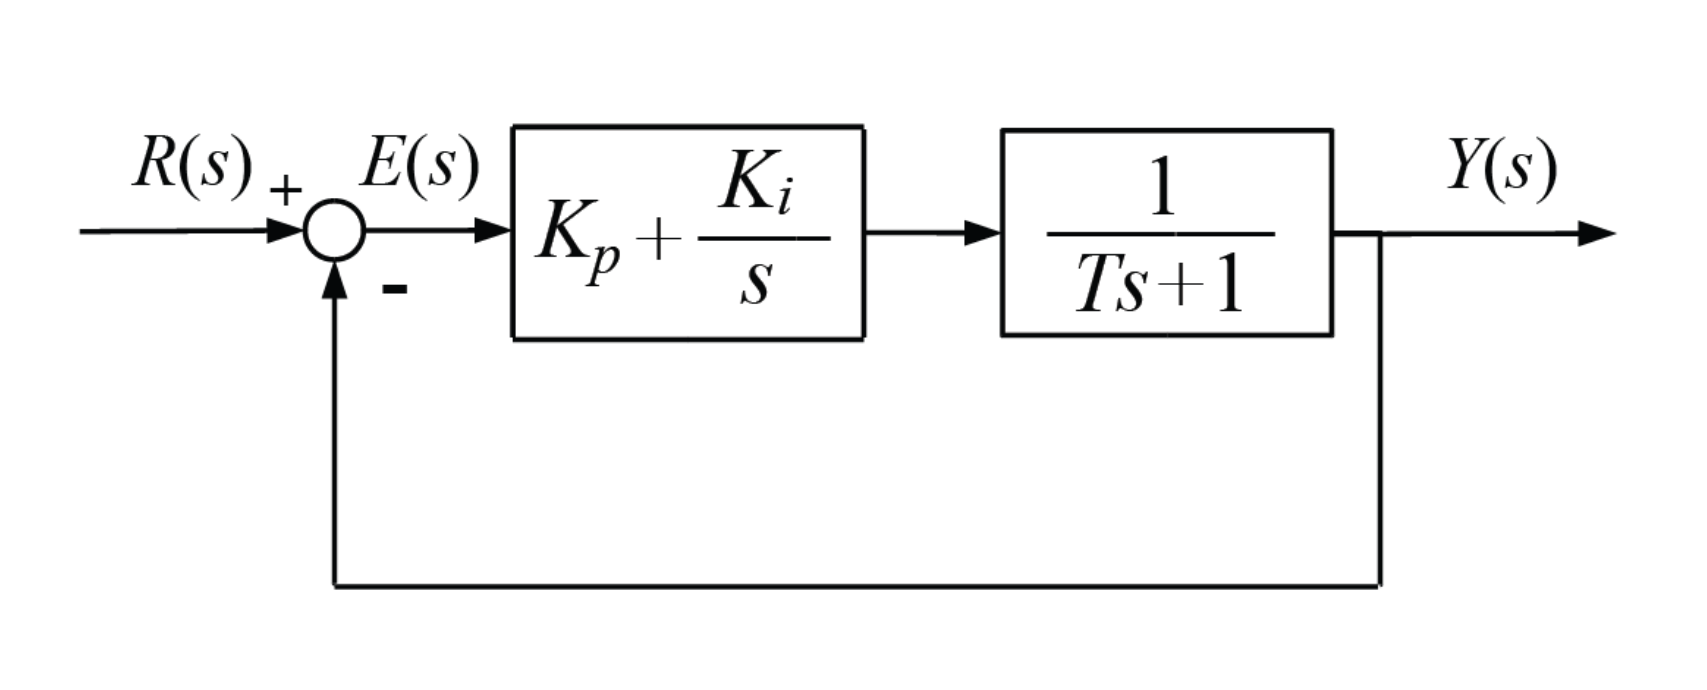

## Pole placement technique 

Solve this problem using the following strategy: 

- Compute the transfer function of the closed loop system 

- Use the above transfer frunction to obtain formulas for real and imaginary parts of the poles of the system in terms of $K_p$ and $K_i$. 

- Use the above formulas to adjust $K_p$ and $K_i$ values so that the poles satisfy the given requirements. 

- For given values of $a$, $b$ and $T$, compute the poles of the system using the values you computed for $K_p$ and $K_i$ and show that the poles satisfy the given requirements.

This is a special case of the general technique called "pole placement", where the desried dynamic response is obtained by adjusting parameters in ways to move the poles to desired locations. 

## Closed loop transfer function

%the plant 
syms Kp Ki s 
syms a b T positve 

PlantTFsym = 1/(T*s+1); 
PITFsym = (s*Kp + Ki)/s; 
A = simplify(PlantTFsym*PITFsym)

$$A = \frac{\mathrm{Ki}+\mathrm{Kp}\,s}{s\,\left(T\,s+1\right)}$$

closedLoopTFsym = simplify(A/(1+A))

$$closedLoopTFsym = \frac{\mathrm{Ki}+\mathrm{Kp}\,s}{\mathrm{Ki}+s+\mathrm{Kp}\,s+T\,s^{2}}$$

## Formulas for real and imaginary parts of the poles 

The poles for the system are the roots of the denominator polynomial. 


r = roots([T,Kp+1,Ki])

$$r = \left(\begin{array}{c} -\frac{\mathrm{Kp}-\sqrt{{\mathrm{Kp}}^{2}+2\,\mathrm{Kp}-4\,\mathrm{Ki}\,T+1}+1}{2\,T}\\ -\frac{\mathrm{Kp}+\sqrt{{\mathrm{Kp}}^{2}+2\,\mathrm{Kp}-4\,\mathrm{Ki}\,T+1}+1}{2\,T} \end{array}\right)$$

The requirements provided are in terms of the real and imaginary parts of the poles. 

The sum of the roots will be equal twice the real part of each. To see this, $\alpha+j\beta$ and $\alpha - j\beta$. Their sum is equal to $2\alpha$, twice the real part of eachof the root. 

%compute sum of the roots 
syms alpha 
alpha = 0.5*simplify(sum(r))

$$alpha = -\frac{\mathrm{Kp}+1}{2\,T}$$

Similarly, the product of the roots will be 

%compute product of roots 
syms beta
eqn = alpha^2 + beta^2 == simplify(r(1)*r(2))

$$eqn = \frac{{\left(\mathrm{Kp}+1\right)}^{2}}{4\,T^{2}}+\beta^{2}=\frac{\mathrm{Ki}}{T}$$

Now that we have the real part and imaginary parts of the roots in terms of the PI gain values, we can use the provided requirements to tune them. Note that the above formulas for the sum of the roots and the product of the roots could have been read directly from the polynomial without having to explicitly compute the roots. 

## Tuning the PI gains

Given requirements are: 

- 
$$\alpha < -a$$


- 
$$\beta < -b$$


Using the first requirement and the formula for $\alpha$ in the previous section: 

 $\alpha = -\frac{K_p+1}{2T} < -a$, $\Rightarrow \frac{K_p+1}{T} > 2a $  $\Rightarrow$ $K_p > 2aT-1$

Using the second requirement and the formula for $\beta$ in the previous section: 


$$ \frac{\mathrm{Ki}}{T} = \frac{{{\left(\mathrm{Kp}+1\right)}}^2 }{4\,T^2 }+\beta^2 \\
>  \frac{{{\left(\mathrm{Kp}+1\right)}}^2 }{4\,T^2 }+ b^2 \\
\Rightarrow K_i > T \left(\frac{{{\left(\mathrm{Kp}+1\right)}}^2 }{4\,T^2 }+ b^2 \right)$$


## Testing the tuned values

a = 5; 
b = 7;
T = 1;
epsilon = 0.1; 

Kp = 2*a*T -1 + epsilon;
Ki = T*( (Kp+1)^2/(4*T^2)+b^2)+epsilon;

Ki = 74.6025

forwardGain = series(tf([Kp,Ki],[1,0]), tf(1,[T,1])  ); 
closedLoopTF = feedback(forwardGain,1); 
pole(closedLoopTF)

ans =   -5.0500 + 7.0071i
  -5.0500 - 7.0071i
